# Projeto do dia 06/11/2020

João Guilherme Martins Jatobá

18.01790-8

ECM303 - Sistemas de Controle

**Boas práticas**

clear all;
clc;
close all;

**Problema com atraso**

Processo:


$$G_p(s)=\frac{1}{s+1}$$


Atraso de 2 segundos na medida:


$$G_{sensor}(s)=\frac{e^{-2s}}{s+1}$$


Desempenho:

- Erro estacionário ao degrau nulo;

- Resposta sem oscilação

$e^{-2s}$ -> atraso de 2 segundos -> $z^{-1}$ - atraso de T segundos, por exemplo T=1 segundo (1 Hz)

Modelar $z^{-2}$ o atraso de 2 segundos com amostragem T = 01 segundo

$e^{-2s}$ -> atraso de 2 segundos -> $z^{-1}$ - atraso de T segundos, por exemplo T= 0.5segundo (2 Hz)

Modelar $z^{-4}$ o atraso de 2 segundos com amostragem T = 0.5 segundo

$e^{-2s}$ -> atraso de 2 segundos -> $z^{-1}$ - atraso de T segundos, por exemplo T=2 segundo (0.5 Hz)

Modelar $z^{-1}$ o atraso de 2 segundos com amostragem T = 2 segundos

**Determinando G(z)**

Gp =tf(1,[1 1])

Gp =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



T=1;
Gpz=c2d(Gp,T,'zoh')

Gpz =
 
    0.6321
  ----------
  z - 0.3679
 
Sample time: 1 seconds
Discrete-time transfer function.



Atraso = tf(1,[1 0 0],T)

Atraso =
 
   1
  ---
  z^2
 
Sample time: 1 seconds
Discrete-time transfer function.




Gsensorz = Gpz*Atraso

Gsensorz =
 
       0.6321
  ----------------
  z^3 - 0.3679 z^2
 
Sample time: 1 seconds
Discrete-time transfer function.



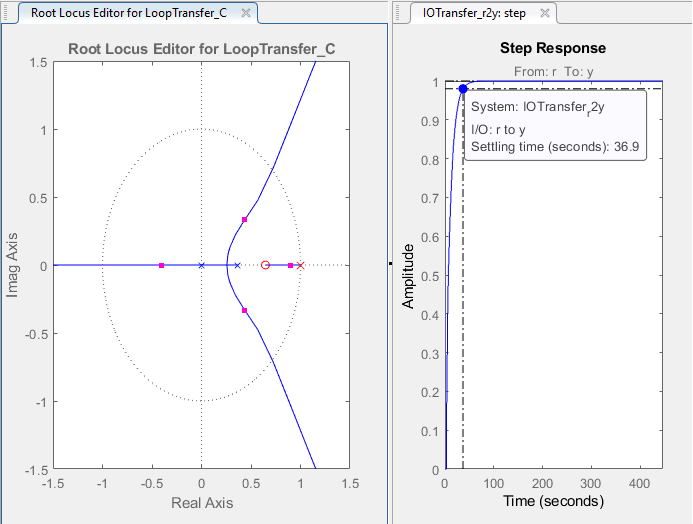

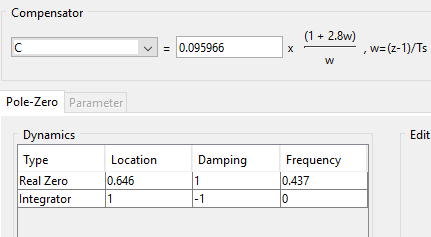

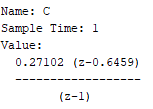

% Ganho do controlador, determinado a partir do sisotool
Gcz = tf([0.27102 -0.27012*0.6459],[1 -1],T)

Gcz =
 
  0.271 z - 0.1745
  ----------------
       z - 1
 
Sample time: 1 seconds
Discrete-time transfer function.




% Ganho de malha aberta em z
Gza = Gcz*Gsensorz

Gza =
 
       0.1713 z - 0.1103
  ----------------------------
  z^4 - 1.368 z^3 + 0.3679 z^2
 
Sample time: 1 seconds
Discrete-time transfer function.




% Ganho de malha fechada em z
Gzf = feedback(Gza,1)

Gzf =
 
                 0.1713 z - 0.1103
  ------------------------------------------------
  z^4 - 1.368 z^3 + 0.3679 z^2 + 0.1713 z - 0.1103
 
Sample time: 1 seconds
Discrete-time transfer function.



**Equação de Diferenças**


$$\frac{Y(z)}{U(z)}=G_z=\frac{0.1713z-0.1103}{z^4-1.368z^3+0.3679z^2+0.1713z-0.1103}$$



$$\frac{Y(z)}{U(z)}=\frac{0.1713z^{-3}-0.1103z^{-4}}{1-1.368z^{-1}+0.3679z^{-2}+0.1713z^{-3}-0.1103z^{-4}}$$



$$Y(z)*(1-1.368z^{-1}+0.3679z^{-2}+0.1713z^{-3}-0.1103z^{-4})= U(z)*(0.1713z^{-3}-0.1103z^{-4})

$$



$$Y[K]=1.368Y[K-1]-0.3679Y[K-2]-0.1713Y[K-3]+0.1103Y[K-4]+0.1713U[K-3]-0.1103U[K-4]$$


**Simulink**